rng('default');

% RF parameters
fc = 38e9;                                       % Carrier frequency (Hz)
c = physconst('LightSpeed');                     % Speed of propagation (m/s)
bw = 100e6;                                      % Bandwidth (Hz)
sampleRate = bw;                                 % Sample rate (Hz)

Pt = 10;                                         % Peak power (W) 
Pt_dB = 10 * log10(Pt) + 30;
Pr = 10;
Pr_dB = 10 * log10(Pr) + 30;
Gtx = 10;                                        % Tx antenna gain (dB)
Grx = 10;                                        % Rx antenna gain (dB) 
NF = 2.9;                                        % Noise figure (dB) 

% Transceiver components
antenna = phased.IsotropicAntennaElement('BackBaffled',false);
transmitter = phased.Transmitter('Gain',Gtx,'PeakPower',Pt);
radiator = phased.Radiator('Sensor',antenna,'OperatingFrequency',fc);
collector = phased.Collector('Sensor',antenna,'OperatingFrequency',fc);
receiver = phased.Receiver('AddInputNoise',true,'Gain',Grx,...
         'NoiseFigure',NF,'SampleRate',sampleRate);

channel = phased.FreeSpace('PropagationSpeed',c,'OperatingFrequency',fc,...
   'SampleRate',sampleRate,'TwoWayPropagation',false);

% Device platform
tgtpos = [8; 4; 0];                              % Device position (m)
tgtvel = [0; 0; 0];                              % Device velocity (m/s)
tgtplatform = phased.Platform('InitialPosition',tgtpos,'Velocity',tgtvel); 

% Anchor platform
anchorpos = [4 12 8;...
            4 1 7;...
            0 0 0];                              % Anchor positions (m)
numAnchor = size(anchorpos,2);                   % Number of anchors 
anchorvel = zeros(3,numAnchor);                  % Anchor velocities (m/s)
anchorplatform = phased.Platform('InitialPosition',anchorpos,'Velocity',anchorvel);

% Configure OFDM waveform
N = 1024;                                        % Number of subbands (OFDM data carriers)
M = 1;                                           % Number of channel samples (OFDM symbols)
freqSpacing = bw/N;                              % Frequency spacing (Hz)
tsym = 1/freqSpacing;                            % OFDM symbol duration  (s)
maxDelay = 200e-9;                               % Maximum delay (s)
rmax = maxDelay*c;                               % Maximum range of interest (m)
tcp = range2time(rmax);                          % Duration of the CP (s)
Ncp = ceil(sampleRate*tcp);                      % Length of the CP in subcarriers
tcp = Ncp/sampleRate;                            % Adjusted duration of the CP (s)
tWave = tsym + tcp;                              % OFDM symbol duration with CP (s)
Ns = N + Ncp; 

% Generate bpsk preamble
preamble_length = 128;
preamble_data = randi([0,1], preamble_length, 1) * 2 - 1;
preamble_ofdm = ifft(preamble_data);
preamble_ofdm = [preamble_ofdm(end/4+1:end); preamble_ofdm];

     0
     0



rxrange = 4

rxang =    180
     0


x =   -0.0000 + 0.0000i
   0.0002 - 0.0000i
   0.0007 + 0.0000i
   0.0005 - 0.0003i
   0.0003 - 0.0000i
   0.0003 + 0.0000i
   0.0004 + 0.0001i
  -0.0000 + 0.0002i
   0.0000 + 0.0001i
   0.0002 + 0.0002i


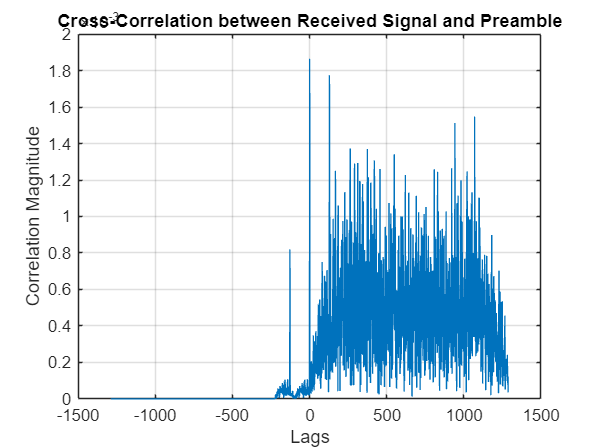

Time of Arrival (TOA) in samples: 1


Time of Arrival (TOA) in seconds: 1e-08


Estimated Distance: using TOA 2.9979 meters


Received Power: 1.6099e-06


RSSI: -27.932


distance_from_PL = 15.6469

  143.1301
         0



rxrange = 5

rxang =   -36.8699
         0


x =    0.0007 + 0.0012i
   0.0003 + 0.0005i
   0.0000 + 0.0004i
   0.0001 + 0.0006i
   0.0002 + 0.0002i
  -0.0001 + 0.0003i
  -0.0000 + 0.0003i
  -0.0001 + 0.0002i
  -0.0001 - 0.0001i
  -0.0001 + 0.0001i


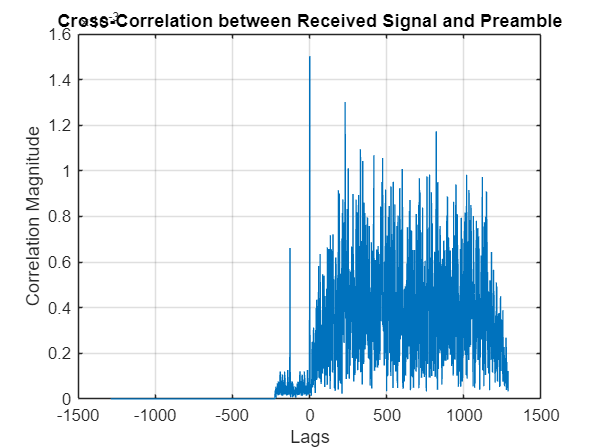

Time of Arrival (TOA) in samples: 2


Time of Arrival (TOA) in seconds: 2e-08


Estimated Distance: using TOA 5.9958 meters


Received Power: 1.0845e-06


RSSI: -29.6479


distance_from_PL = 19.0643

   -90
     0



rxrange = 3

rxang =     90
     0


x =    0.0004 - 0.0006i
  -0.0000 - 0.0004i
   0.0001 - 0.0012i
  -0.0006 - 0.0004i
   0.0003 - 0.0004i
  -0.0001 - 0.0005i
   0.0002 - 0.0005i
   0.0003 + 0.0003i
   0.0000 - 0.0002i
   0.0004 - 0.0004i


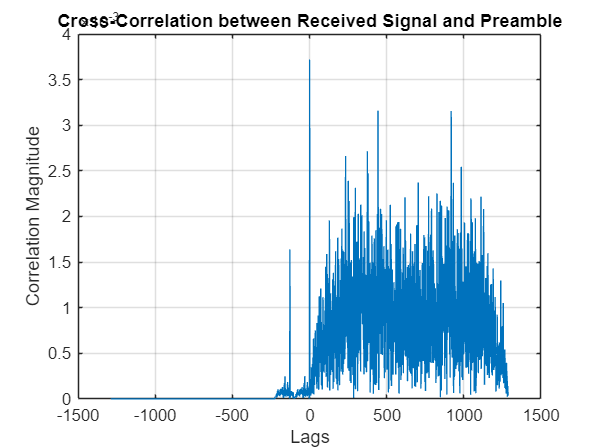

Time of Arrival (TOA) in samples: 1


Time of Arrival (TOA) in seconds: 1e-08


Estimated Distance: using TOA 2.9979 meters


Received Power: 5.6533e-06


RSSI: -22.477


distance_from_PL = 8.3498

% Estimated channel
X = cell(1,numAnchor);
ranges = zeros(1, numAnchor);
toa_range_corr = zeros(1, numAnchor);
estimated_ranges_RSSI = zeros(1, numAnchor);

for idxAnchor = 1:numAnchor

    % Modulate OFDM waveform with BPSK modulation on each data carrier
    bpskSymbol = randi([0,1],[N M])*2-1;             % BPSK symbol on each data carrier
    sigmod = ifft(ifftshift(bpskSymbol,1),[],1);     % OFDM symbols
    sig = sigmod([end-Ncp+(1:Ncp),1:end],:);         % OFDM symbols with cyclic prefix
    sig = sig/max(abs(sig),[],'all');                % Power-normalized OFDM signal

    % Generate preamble for toa calculation
    ofdm_symbol = [preamble_ofdm; sig];


    % Initialize estimated channel
    x = complex(zeros(size(ofdm_symbol)));

    % Transceiver chain
    for m = 1:M

        % Update radar and device positions
        [tx_pos,tx_vel] = anchorplatform(tWave);
        [rx_pos,rx_vel] = tgtplatform(tWave);

        % Calculate the transmit angle
        [~,txang] = rangeangle(rx_pos,tx_pos(:,idxAnchor)); 
        disp(txang);

        % Transmitted signal
        txsig = transmitter(ofdm_symbol);

        % Radiate signal towards the receiver 
        radtxsig = radiator(txsig(:,m),txang); 

        % Propagate the signal
        chansig = channel(radtxsig,tx_pos(:,idxAnchor),rx_pos,...
                  tx_vel(:,idxAnchor),rx_vel);

        % Calculate the receive angle
        [rxrange,rxang] = rangeangle(tx_pos(:,idxAnchor),rx_pos);
        rxrange
        rxang

        ranges(idxAnchor) = rxrange;

        % Collect signal at the receive antenna
        rxsig = collector(chansig,rxang);

        % Receive signal at the receiver
        x(:,m) = receiver(rxsig);
        x

        % Correlating
        [cross_corr, lags] = xcorr(rxsig, preamble_ofdm);

        figure;
        plot(lags, abs(cross_corr));
        title('Cross-Correlation between Received Signal and Preamble');
        xlabel('Lags');
        ylabel('Correlation Magnitude');
        grid on;

        % Find the index of the maximum correlation peak
        [~, max_idx] = max(abs(cross_corr));

        toa_sample = lags(max_idx);

        toa_time = toa_sample / sampleRate;

        toa_distance = toa_time * c;  % 'c' is the speed of light
        toa_range_corr(idxAnchor) = toa_distance;

        disp(['Time of Arrival (TOA) in samples: ', num2str(toa_sample)]);
        disp(['Time of Arrival (TOA) in seconds: ', num2str(toa_time)]);
        disp(['Estimated Distance: using TOA ', num2str(toa_distance), ' meters']);

        % Calculate RSSI
        receivedPower = mean(abs(x).^2);
        disp(['Received Power: ', num2str(receivedPower)]);
        RSSI = 10 * log10(receivedPower) + 30;
        disp(['RSSI: ', num2str(RSSI)]);

        % Calculate Path Loss
        PL = Pt_dB + Gtx + Grx - RSSI;

        K = 20 * log10(4 * pi * fc / c);
        distance_from_PL = 10^((PL - K) / 20);
        distance_from_PL
        
        estimated_ranges_RSSI(idxAnchor) = distance_from_PL;
    end

    % Remove the cyclic prefix 
    xrmvcp = x((Ncp+1):(Ncp+N),:);

    % Demodulate the received OFDM signal
    xdemod = fftshift(fft(xrmvcp,[],1),1);

    % Remove BPSK symbol on each data carrier
    X{idxAnchor} = xdemod./bpskSymbol;

    % Reset platforms for the next anchor
    reset(anchorplatform);
    reset(tgtplatform);
end

ranges

ranges =      4     5     3


estimated_ranges_RSSI

estimated_ranges_RSSI =    15.6469   19.0643    8.3498


toa_range_corr

toa_range_corr =     2.9979    5.9958    2.9979


tgtpos2D = tgtpos(1:2,:)

tgtpos2D =      8
     4


anchorPositions2D = anchorpos(1:2,:)

anchorPositions2D =      4    12     8
     4     1     7


anchorsXCoord = anchorpos(1,:);
anchorsYCoord = anchorpos(2,:);

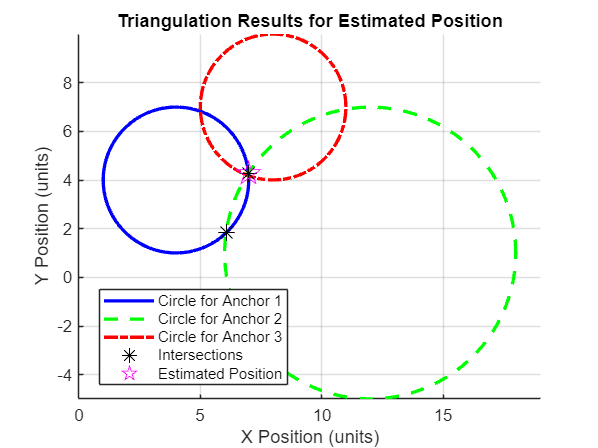

% Choose two circles to intersect, 1 and 2
i = 1; j = 2;
x1 = anchorPositions2D(1, i);
y1 = anchorPositions2D(2, i);
r1 = toa_range_corr(i);
x2 = anchorPositions2D(1, j);
y2 = anchorPositions2D(2, j);
r2 = toa_range_corr(j);

% Calculate the intersection of these two circles
d = sqrt((x2 - x1)^2 + (y2 - y1)^2);
a = (r1^2 - r2^2 + d^2) / (2 * d);
h = sqrt(r1^2 - a^2);
x0 = x1 + a * (x2 - x1) / d;
y0 = y1 + a * (y2 - y1) / d;
ix1 = x0 + h * (y2 - y1) / d;
iy1 = y0 - h * (x2 - x1) / d;
ix2 = x0 - h * (y2 - y1) / d;
iy2 = y0 + h * (x2 - x1) / d;

% Validate intersection points with the third circle
k = 3;
x3 = anchorPositions2D(1, k);
y3 = anchorPositions2D(2, k);
r3 = toa_range_corr(k);

% Check if either point is within the third circle
if sqrt((ix1 - x3)^2 + (iy1 - y3)^2) <= r3
    estimated_position = [ix1, iy1];
elseif sqrt((ix2 - x3)^2 + (iy2 - y3)^2) <= r3
    estimated_position = [ix2, iy2];
else
    estimated_position = [NaN, NaN];
end

figure; hold on;
theta = linspace(0, 2*pi, 100);
colors = ['b', 'g', 'r']; 
markers = {'o', '+', 's'}; 
lineStyles = {'-', '--', '-.'};
legendEntries = cell(1, 3);

for i = 1:3
    x_circle = anchorPositions2D(1, i) + toa_range_corr(i) * cos(theta);
    y_circle = anchorPositions2D(2, i) + toa_range_corr(i) * sin(theta);
    plot(x_circle, y_circle, 'Color', colors(i), 'LineStyle', lineStyles{i}, 'LineWidth', 2, ...
        'DisplayName', sprintf('Circle for Anchor %d', i));
    legendEntries{i} = sprintf('Circle for Anchor %d', i);
end

% Plot intersection points
plot([ix1, ix2], [iy1, iy2], 'k*', 'MarkerSize', 10, 'DisplayName', 'Intersections');

% Plot estimated position
plot(estimated_position(1), estimated_position(2), 'p', 'Color', 'm', 'MarkerSize', 15, ...
    'DisplayName', 'Estimated Position');

% Enhancing the legend and plot aesthetics
legend(legendEntries{:}, 'Intersections', 'Estimated Position', 'Location', 'best');
xlabel('X Position (units)');
ylabel('Y Position (units)');
title('Triangulation Results for Estimated Position');
grid on; % Adding a grid
axis equal; % Keeping the aspect ratio equal

hold off;


estimated_position 

estimated_position =     6.9843    4.2853



diff = tgtpos2D - estimated_position';
sqDiff = diff.^2;
meanSqDiff = mean(sqDiff);
rmse = sqrt(meanSqDiff);
disp("RMSE for estimated position: ");

RMSE for estimated position: 


disp(rmse);

    0.7460



mu = estimated_position';
observedRanges = toa_range_corr;

anchorPositions2D;

nAnchors = size(anchorPositions2D, 2);

measuredRanges = sqrt(sum((mu - anchorPositions2D).^2))

measuredRanges =     2.9979    5.9958    2.8985



r = observedRanges' - measuredRanges'; %residuals

H = zeros(nAnchors, 2);
for i = 1:nAnchors
    H(i, :) = (mu - anchorPositions2D(:, i))' / measuredRanges(i);
    disp(H);
end

    0.9955    0.0952
         0         0
         0         0

    0.9955    0.0952
   -0.8365    0.5479
         0         0

    0.9955    0.0952
   -0.8365    0.5479
   -0.3504   -0.9366




r

r =    -0.0000
         0
    0.0994


H

H =     0.9955    0.0952
   -0.8365    0.5479
   -0.3504   -0.9366



delta_mu = (H' * H) \ (H' * r);

mu_hat = mu + delta_mu;

disp('Refined target position:')

Refined target position:


disp(mu_hat)

    6.9636
    4.2062




diff = tgtpos2D - mu_hat;
sqDiff = diff.^2;
meanSqDiff = mean(sqDiff);
rmse = sqrt(meanSqDiff);
disp("RMSE for Refined position: ");

RMSE for Refined position: 


disp(rmse);

    0.7472

